close all;
clear all;

load('Input_norm_full')

npoints=length(input_norm);  % Number of points
chip = 100e6;    % 100 MHz signal bandwidth
Fs = chip * 10;  % Sampling frequency

% Time vector
t = (0:npoints-1)/Fs;


sanityIn = input_norm(90001:120000); % Extract the data
t2 = (0:length(sanityIn)-1)/Fs;
sanityIn = sanityIn .* 10^(22.5/20); % Scale the values

power_avg_input = trapz(t2, abs(sanityIn).^2) / ((t2(end) - t2(1))*100);  % Using numerical integration

power_input = 10 * log10(power_avg_input/1e-3);
fprintf('Matlab input data Average Power (dBm): %f dBm\n', power_input);

Matlab input data Average Power (dBm): 21.859690 dBm



%writematrix(sanityIn.', 'Mem22dB_predist.csv'); % Transpose and save as CSV


%%AMAM_AMPM_function_maker

%%%load data and output gain and phase functions
%clear all
load('PA_data')
%%% extend Pin, Gain and Phase
%%% expresses gain in dB as function of input in dBm
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Phase_EC34 = PhasePA;
Gain_EC34 = GainPA;
pinxx=[-1000 Pin 20+max(Pin)];
dpinx=Pin(length(Pin))-Pin(length(Pin)-1);
dPhx=Phase_EC34(length(Pin))-Phase_EC34(length(Pin)-1);
gaxx=[ Gain_EC34(1) Gain_EC34  Gain_EC34(length(Pin))-20];
phxx=[ Phase_EC34(1) Phase_EC34  Phase_EC34(length(Pin))+20*dPhx/dpinx];

npoints=30000;
%npoints = 2^16
%this increases the length of the cases 
rand('state', 51234); 
%rand('state', 500);
chip = 100e6;    %% 100MHz signal bandwidth
Amax=1;
Fs = chip*10;   %sampling frequency   is  high

% Time vector
t = (0:npoints-1)/Fs;

load('IQ_xItest.mat')
%%input power coefficienct in dBm

xI = xI_actual;
Pinc=7;
%%% change this to correspond to different input powers
PinpkdBm=Pinc+10;    %%%  peak power in dBm for maximum env = 1 V amplitude into 50 ohm load
%
%
% %%%% determine output envelope yout using gainmeas, phasemeas or gaxx and
% phxx

% Input Power

env = abs(xI);

% av_power_xI = trapz(t, abs(xI).^2) / ((t(end) - t(1))*100);  % Using numerical integration
% fprintf('xI input using Integral: %f\n', av_power_xI);
% 
% power_dBm_xI = 10 * log10(av_power_xI/1e-3);
% fprintf('xI input Power in dBm: %f dBm\n', power_dBm_xI);

% Assuming xI and yout are already defined as row vectors (1x65536 complex double)


% %%see spectrum of output
load('Mem7dB_predist_predictions.mat')

xI_predictT = xI_predict;

av_power_xI = trapz(t, abs(xI_predict).^2) / ((t(end) - t(1))*100);  % Using numerical integration
fprintf('xI predicted input using Integral: %f\n', av_power_xI);

xI predicted input using Integral: 0.005967



power_dBm_xI = 10 * log10(av_power_xI/1e-3);
fprintf('xI predicted input Power in dBm: %f dBm\n', power_dBm_xI);

xI predicted input Power in dBm: 7.757440 dBm



disp(sprintf('NN predicted xI predistortion Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(xI_predict))/rms(abs(xI_predict)))));

NN predicted xI predistortion Peak-to-average ratio: 11.70 dB



envxI=abs(xI_predictT);    %%%output baseband complex voltage
PoutpkW=max(envxI)^2/2/50     %% peak output power in W

PoutpkW = 0.0883

PoutpkdBm=10*log10(PoutpkW)+30     %%% peak output power in dBm

PoutpkdBm = 19.4615

% disp(sprintf('Baseband Peak-to-average ratio yout_ideal: %1.2f dB', 20*log10(max(abs(yout_ideal))/rms(abs(yout_ideal)))));

%%see spectrum of output
figure(140)

[P_predist_input_predist, F_predist_input_predist] = spec_plot(xI_predict,1/Fs,135,'NN predicted pre-distorted memory effect signal');

ACPR: -26.54


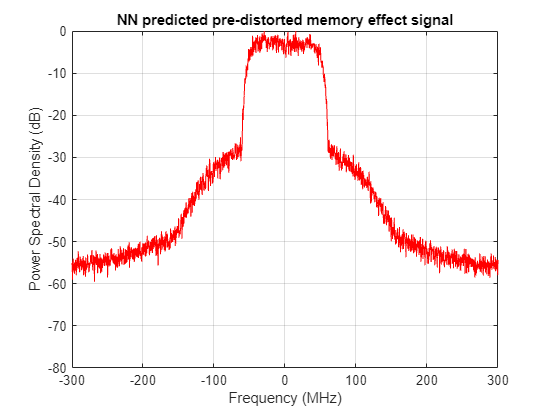

axis([-300 300 -80 0])

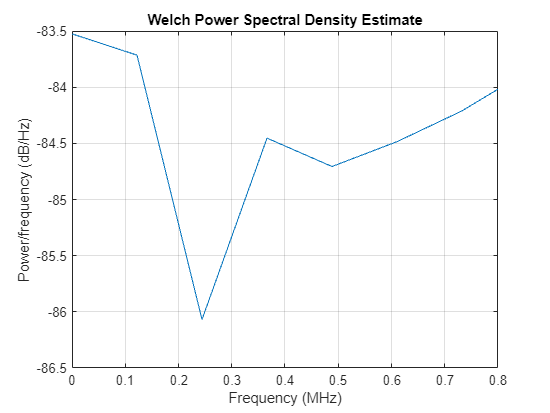

figure(1351)
pwelch(xI_predict,[],[],[],Fs)      %%% spectrum of output
xlim([0 0.8])


disp(sprintf('NN predicted Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(xI_predictT))/rms(abs(xI_predictT)))));

NN predicted Peak-to-average ratio: 11.70 dB




% Phase and magnitude plots
PoutpkW4=max(abs(xI_predictT))^2/2/50     %% peak output power in W

PoutpkW4 = 0.0883

PoutpkdBm4=10*log10(PoutpkW4)+30     %%% peak output power in dBm

PoutpkdBm4 = 19.4615

fprintf('xI NN peak predistorted Power in dBm: %f dBm\n', PoutpkdBm4);

xI NN peak predistorted Power in dBm: 19.461541 dBm



xI_norm = xI_predict / max(abs(xI_predict));

xI_predict = xI_norm;

envpredict = abs(xI_predict);

Pinc = 7;

%env = abs(xI) or abs(yout)

%steps

xenvNN = abs(xI_predict);

% Replace NaN values in yout_nn_pd with the average of the variable



%Trying to find inref for yout' signal:



% figure(97)
% plot(1:1000,envbigxI(1:1000),1:1000,envyoutNN(1:1000))
% legend('yout Ideal', 'yout Predistorted')
% title('Envelop plot of PA yout and NN yout predistorted')

disp(sprintf('xI Predistorted Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(xI_predict))/rms(abs(xI_predict)))));

xI Predistorted Peak-to-average ratio: 11.70 dB



%Normalize signals
xI_input_norm = xI_actual / max(abs(xI_actual));
xI_predict_norm = xI_predict / max(abs(xI_predict));

writematrix(xI_predict_norm.', 'normalized_predistorted_7dB.csv'); % Transpose and save as CSV

spec_plot(xI_predict_norm,1/Fs,135,'Normalized pre-distorted memory effect signal');

ACPR: -26.54


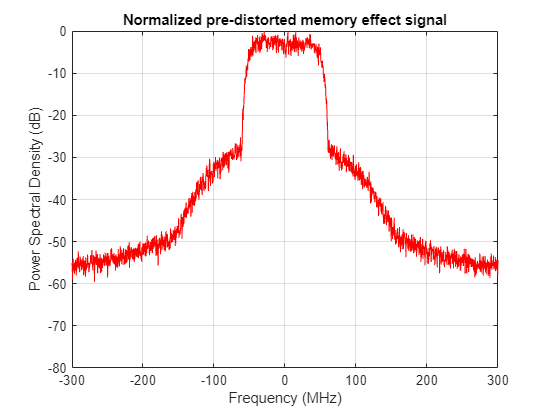

axis([-300 300 -80 0])

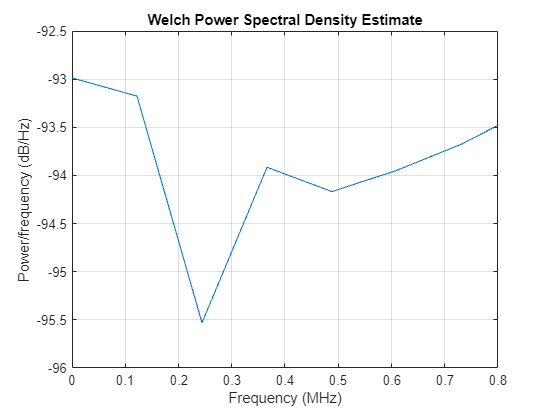

figure(1351)
pwelch(xI_predict,[],[],[],Fs)      %%% spectrum of output
xlim([0 0.8])


% Compute the RMSE
error_vector = xI_predict_norm - xI_input_norm; % Difference between vectors
rmse = sqrt(mean(abs(error_vector).^2)); % Root Mean Square Error

% Normalize RMSE to calculate percentage error
rms_actual = sqrt(mean(abs(xI_predict_norm).^2)); % RMS of the actual vector
rmse_percent = (rmse / rms_actual) * 100 % Percentage RMSE

rmse_percent = 156.5709


peak_actual = max(abs(xI_predict_norm));
rmse_percent_peak = (rmse / peak_actual) * 100; % RMSE normalized by peak
fprintf('RMSE Predicted xI  Error (Peak-Normalized): %.2f%%\n', rmse_percent_peak);

RMSE Predicted xI  Error (Peak-Normalized): 40.69%






%disp(sprintf('NN predicted xI predistortion Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(xI_predict))/rms(abs(xI_predict)))));
%disp(sprintf('yout predistorted Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(yout_nn_pd))/rms(abs(yout_nn_pd)))));


load('dB7_predist_final.mat')
% 
% npoints=length(output_predist_7dB);  % Number of points
%t = (0:npoints-1)/Fs;
% 
% figure(137)
% [P_predist_output_predist, F_predist_output_predist] = spec_plot(output_predist_7dB,1/Fs,135,'Simulated PA Predistorted output 7dB');
% axis([-300 300 -100 0])
% figure(1351)
% 
% yout_out_av = trapz(t, abs(output_predist_7dB).^2) / ((t(end) - t(1))*100);  % Using numerical integration
% % fprintf('yout output using Integral: %f\n', yout_out_av);
% 
% power_dBm_y_out = 10 * log10(yout_out_av/1e-3);
% fprintf('yout output Power in dBm: %f dBm\n', power_dBm_y_out);
% 
% disp(sprintf('Predistorted Sim output xI predistortion Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(output_predist_7dB))/rms(abs(output_predist_7dB)))));
% 
% PoutpkW4=max(output_predist_7dB)^2/2/50     %% peak output power in W
% PoutpkdBm4=10*log10(PoutpkW4)+30     %%% peak output power in dBm
% fprintf('yout NN peak predistorted Power in dBm: %f dBm\n', PoutpkdBm4);

load('predist_results_ProfAsbeckV3.mat')

npoints=length(Predist_final);  % Number of points
t = (0:npoints-1)/Fs;

output_dist_7dB = Predist_final;
figure(137)
[P_predist_output_dist, F_predist_output_dist] =spec_plot(output_dist_7dB,1/Fs,135,'Simulated PA output 7dB');

ACPR: -38.24


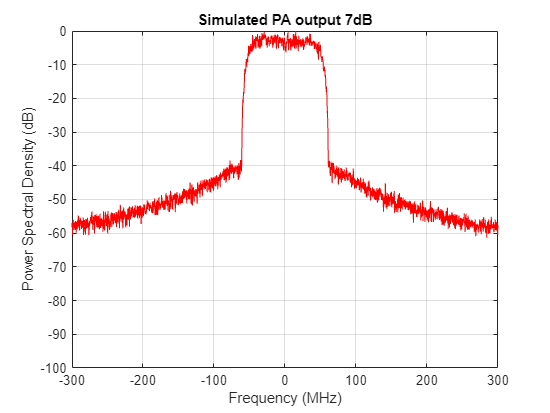

axis([-300 300 -100 0])

figure(1351)

yout_out_av = trapz(t, abs(output_dist_7dB).^2) / ((t(end) - t(1))*100);  % Using numerical integration
% fprintf('yout output using Integral: %f\n', yout_out_av);

power_dBm_y_out = 10 * log10(yout_out_av/1e-3);
fprintf('Sim out output Power in dBm: %f dBm\n', power_dBm_y_out);

Sim out output Power in dBm: 21.324776 dBm



disp(sprintf('Sim output xI predistortion Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(output_dist_7dB))/rms(abs(output_dist_7dB)))));

Sim output xI predistortion Peak-to-average ratio: 9.68 dB



PoutpkW4=max(output_dist_7dB)^2/2/50     %% peak output power in W

PoutpkW4 = 1.1985 + 0.3871i

PoutpkdBm4=10*log10(PoutpkW4)+30     %%% peak output power in dBm

PoutpkdBm4 = 31.0019 + 1.3568i

fprintf('Sim out peak predistorted Power in dBm: %f dBm\n', PoutpkdBm4);

Sim out peak predistorted Power in dBm: 31.001910 dBm



load('IQ_input10dB.mat')

figure(137)
[P_predist_input_ideal, F_predist_input_ideal] = spec_plot(MatlabInput,1/Fs,135,'10dB Ideal');

ACPR: -50.14


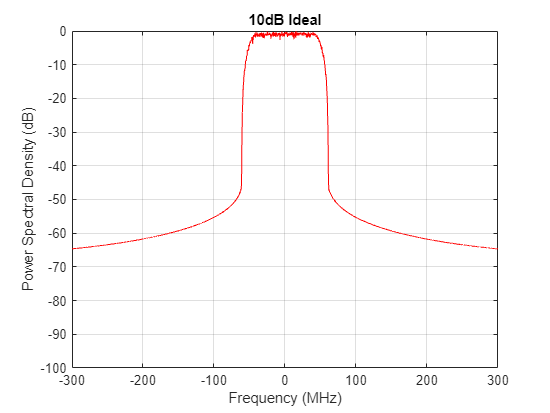

axis([-300 300 -100 0])

figure(1351)

%save('SpecPredistData.mat', 'P_predist_input_ideal', 'F_predist_input_ideal', 'P_predist_output_dist','F_predist_output_dist','P_predist_output_predist', 'F_predist_output_predist', 'P_predist_input_predist', 'F_predist_input_predist');

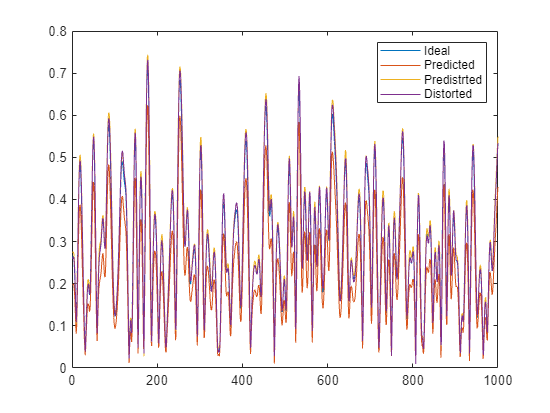

load('IQ_xItest.mat')

output_dist_7dB = output_dist_7dB(1:30000);
output_predist_7dB = output_predist_7dB(1:30000);

%save('predistRaw.mat', 'xI', 'xI_predict', 'output_dist_7dB', 'output_predist_7dB')

%Normalize signals
xI_input_norm = xI_actual / max(abs(xI_actual));
xI_predict_norm = xI_predict / max(abs(xI_predict));

%Trying to find inref for yout' signal:
inMag3 = abs(output_predist_7dB);
inPhase3 = angle(output_predist_7dB);
inRefMag3 = inMag3/6.02;
inRefAngle3 = inPhase3 + (76.2/180)*3.1416;

%this is wrong
%inRef = (inRefMag .* exp(1i * inRefAngle))/10^((Pinc)/20);
inRef3 = (inRefMag3 .* exp(1i * inRefAngle3));

yout_valid_norm = output_predist_7dB / max(abs(output_predist_7dB));
yout_dist_norm = output_dist_7dB / max(abs(output_dist_7dB));

PA_distorted_out = abs(xI_predict_norm(1:1000));
predicted_predist_input = abs(yout_dist_norm(1:1000));
ideal_predist = abs(yout_valid_norm(1:1000));
predist_output = abs(xI_input_norm(1:1000));




% figure(95)
plot(1:1000,abs(xI_input_norm(1:1000)),1:1000,abs(xI_predict_norm(1:1000)),1:1000,abs(yout_valid_norm(1:1000)),1:1000,abs(yout_dist_norm(1:1000)))
legend('Ideal', 'Predicted','Predistrted','Distorted')


save('envelopePredistdata.mat', 'ideal_predist', 'predicted_predist_input', 'PA_distorted_out', 'predist_output');


% Compute the RMSE
error_vector = xI_predict_norm - xI_input_norm; % Difference between vectors
rmse = sqrt(mean(abs(error_vector).^2)); % Root Mean Square Error

% Normalize RMSE to calculate percentage error
rms_actual = sqrt(mean(abs(xI_predict_norm).^2)); % RMS of the actual vector
rmse_percent = (rmse / rms_actual) * 100 % Percentage RMSE

rmse_percent = 156.5709


peak_actual = max(abs(xI_predict_norm));
rmse_percent_peak = (rmse / peak_actual) * 100; % RMSE normalized by peak
fprintf('RMSE Predicted xI  Error (Peak-Normalized): %.2f%%\n', rmse_percent_peak);

RMSE Predicted xI  Error (Peak-Normalized): 40.69%



yout_dist_norm = output_dist_7dB(1:30000);
% Compute the RMSE
error_vector = yout_dist_norm - xI_input_norm; % Difference between vectors
rmse = sqrt(mean(abs(error_vector).^2)); % Root Mean Square Error

% Normalize RMSE to calculate percentage error
rms_actual = sqrt(mean(abs(yout_dist_norm).^2)); % RMS of the actual vector
rmse_percent = (rmse / rms_actual) * 100 % Percentage RMSE

rmse_percent = 91.2405


peak_actual = max(abs(error_vector));
rmse_percent_peak = (rmse / peak_actual) * 100; % RMSE normalized by peak
fprintf('RMSE output  Error (Peak-Normalized): %.2f%%\n', rmse_percent_peak);

RMSE output  Error (Peak-Normalized): 32.79%



% Compute the RMSE
yout_valid_norm = yout_valid_norm(1:30000);

%yout_predist_norm = yout_predist_norm / max(yout_predist_norm)

error_vector = yout_valid_norm - xI_input_norm; % Difference between vectors
rmse = sqrt(mean(abs(error_vector).^2)); % Root Mean Square Error

% Normalize RMSE to calculate percentage error
rms_actual = sqrt(mean(abs(yout_valid_norm).^2)); % RMS of the actual vector
rmse_percent = (rmse / rms_actual) * 100 % Percentage RMSE

rmse_percent = 5.8453


peak_actual = max(abs(yout_valid_norm));
rmse_percent_peak = (rmse / peak_actual) * 100; % RMSE normalized by peak
fprintf('RMSE Output Predistorted  Error (Peak-Normalized): %.2f%%\n', rmse_percent_peak);

RMSE Output Predistorted  Error (Peak-Normalized): 1.97%
